# Simplified antievent analysis - tube - binary - remove onsets

### 1 Simplify events by removing M duplicates and selecting specified K 

If multiple events are significant starting at the same time for the same length, only keep the one with highest number of neurons 

% get simplified events and antievents
load('dTT_SYN_18Pair_R3_10032020.mat')
load('em_18p_antievent_binary_0.05.mat')
anti=rem_dup_em(anti,'nround',1);
[N,nm]=size(anti{1,1}.eve);

Find events with 4 specified lengths: 5s, 20s, 40s, 100s 

klist={5,20,40,100};% find events separately for each k
% antievents
allt=cell(N,nm);allm=cell(N,nm);allk=cell(N,nm);
for p=1:N
    for m=1:nm
        [allt{p,m},allm{p,m},allk{p,m}]=alltmk(klist,anti{1,1}.K{p,m},anti{1,1}.M{p,m},anti{1,1}.time{p,m});
    end
end
anti{1,1}.allt=allt;anti{1,1}.allm=allm;anti{1,1}.klist=klist;anti{1,1}.allk=allk;

### Plot events

After selecting events of the 4 lengths, plot each event as a line. Interacting mice are plotted together with correlaponding rasters.

Orange = subordinate animal events; Blue = dominant animal events

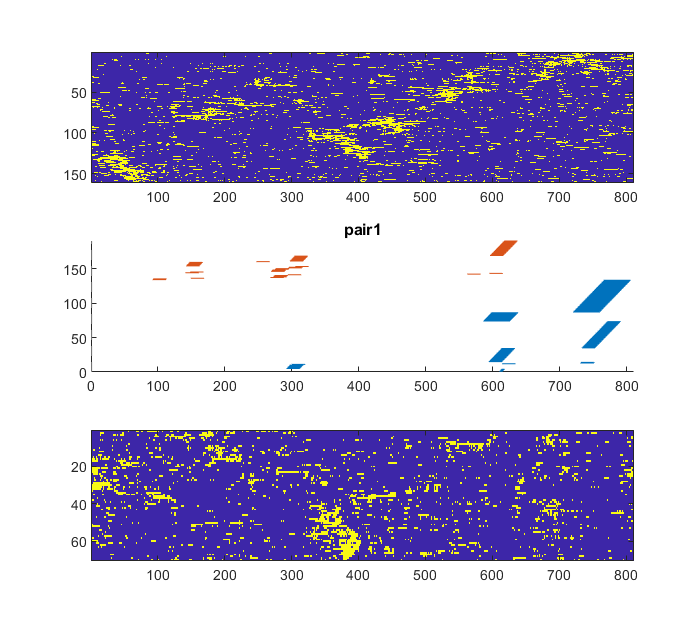

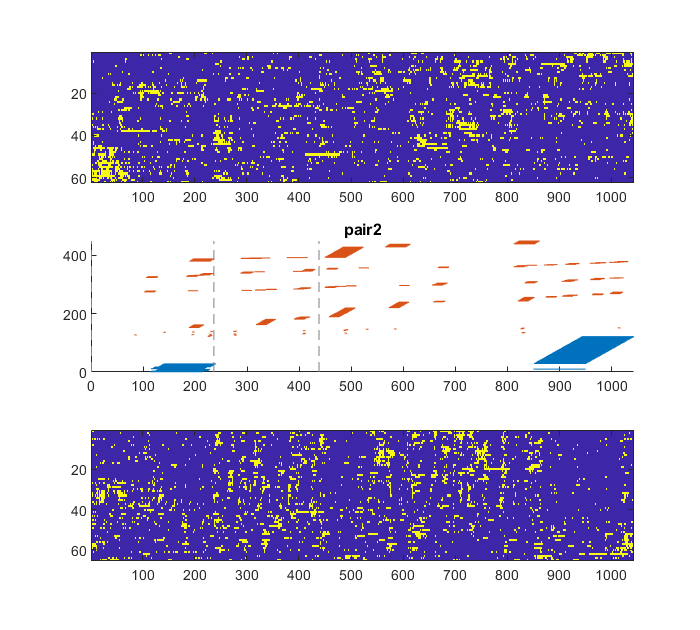

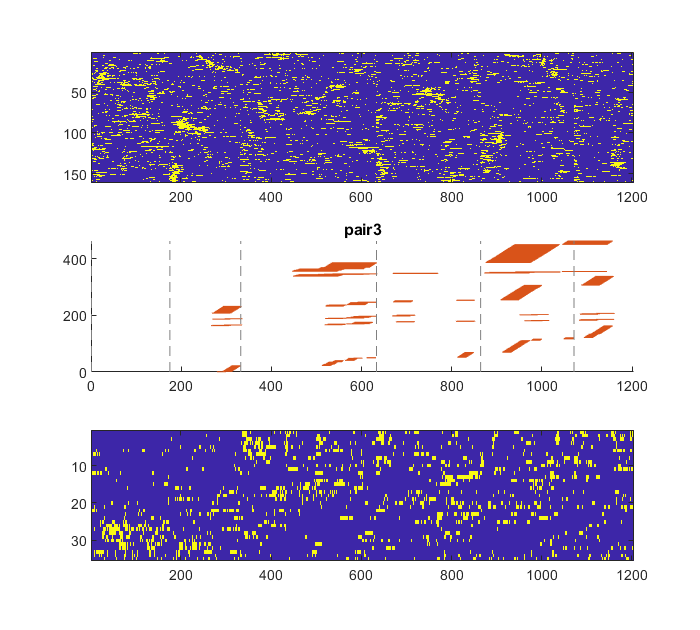

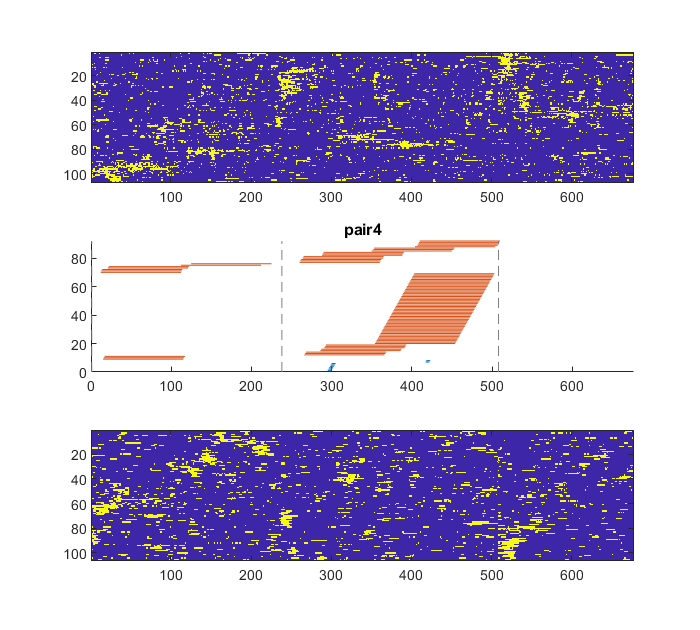

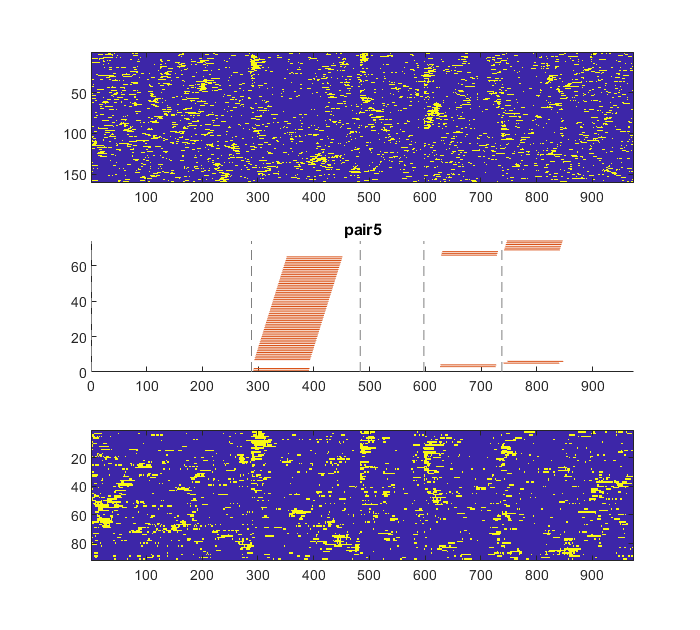

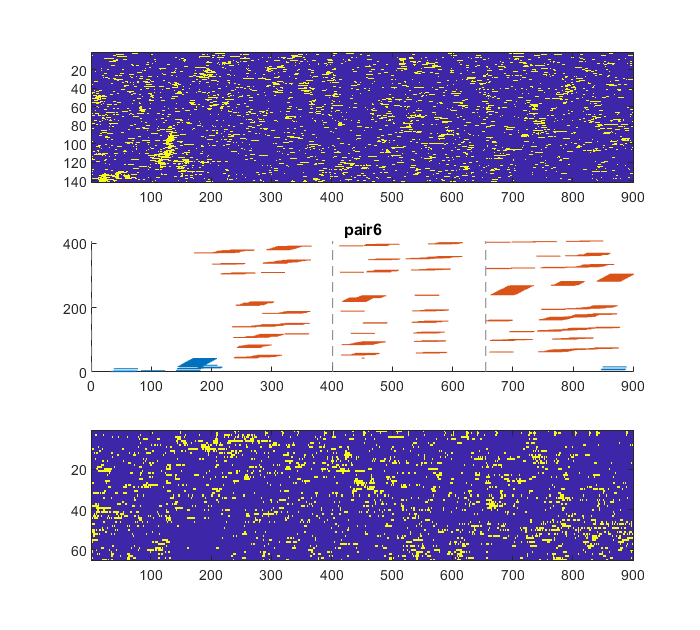

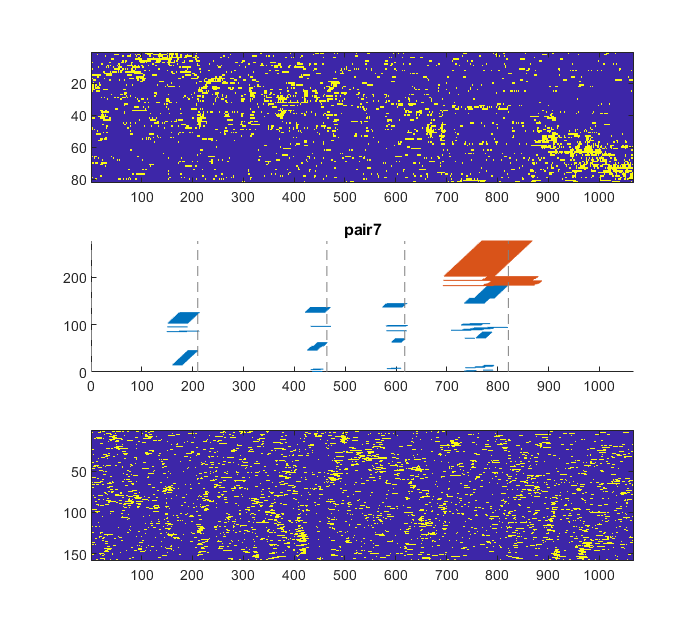

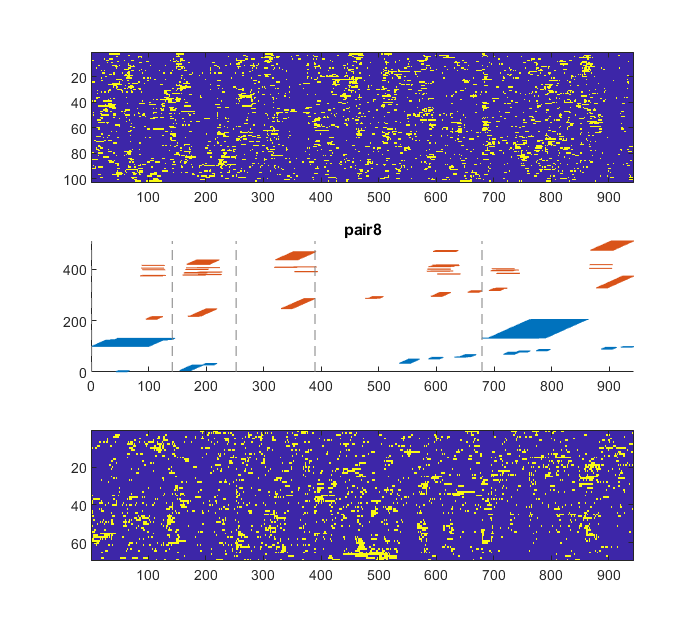

close all
for p=1:N
    f=figure;f.Position(4)=1.2*f.Position(4);
    subplot(3,1,2)
    totalt=size(anti{1,1}.ca_cl{p,1},2);
    et11=anti{1,1}.allt{p,1};
    et21=anti{1,1}.allt{p,2};
    maxy=eventplot_lines(et11,anti{1,1}.allk{p,1},1:totalt);
    hold on
    maxy=eventplot_lines(et21,anti{1,1}.allk{p,2},1:totalt,'y0',maxy,"col",[0.8500 0.3250 0.0980]);
    onset = sum(reshape(E{p}{1}.BehaviorVectors(1:30*totalt,4),30,totalt),1);
    plot(repmat(find(onset),2,1),repmat([0;maxy],1,length(find(onset))),'--','Color',0.5*[1,1,1])
    hold off
    xlim([0 totalt]);ylim([0 maxy])
    title(sprintf('pair%d',p))
    % NOTE - run this title only after synchronization percentage is derived !!
      % here plotting K=5,20,40,100
    %title(sprintf('pair%d,%%syn5s=%.2g,%%syn20s=%.2g,%%syn40s=%.2g,%%syn100s=%.2g',p,synwithin(1,p),synwithin(2,p),synwithin(3,p),synwithin(4,p)))
    % -------
    subplot(3,1,3)
    S0=anti{1,1}.ca_cl{p,1};
    ops.iPC=1:35;
    [isort1, ~, ~] = mapTmap(S0, ops);
    imagesc(S0(isort1,:))
    subplot(3,1,1)
    S0=anti{1,1}.ca_cl{p,2};
    ops.iPC=1:35;
    [isort1, ~, ~] = mapTmap(S0, ops);
    imagesc(S0(isort1,:))
end

Note: The 20s after each trial onsets are removed to control for synchronization caused by trial onsets 

Note: remove pairs 3,5,14 for further analysis for lack of events

test=[1,2,4,6:13,15:18];
N=15;

### Q1: Compare number/coverage of events in Dom&Sub animals 

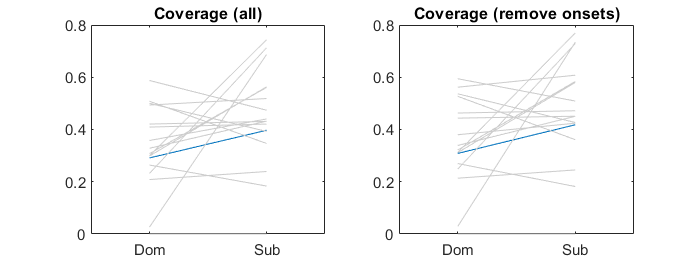

% number of events
neve=zeros(N,nm);coverage1=zeros(N,nm);coverage2=zeros(N,nm);
for ind=1:N
    p=test(ind);
    for m=1:nm
        % coverage of events
        l=size(anti{1,1}.ca_cl{p,m},2);
        % first round
        [totalcov]=evecoverage(l,anti{1,1}.allt{p,m},anti{1,1}.allk{p,m});
        coverage1(p,m)=sum(totalcov)./l;
        % identify and remove trial onsets 
        onset = find(sum(reshape(E{p}{1}.BehaviorVectors(1:30*l,4),30,l),1));
        keep=ones(1,l);
        for i=1:length(onset)
            keep(onset(i):onset(i)+19)=0;
        end
        totalcov=totalcov(logical(keep));
        coverage2(p,m)=sum(totalcov)./sum(keep);
    end
end
f=figure;f.Position(4)=0.5*f.Position(4);
subplot(1,2,1)
plot(mean(coverage1)','-');hold on
plot(coverage1','-',"Color",0.8*[1,1,1]);xlim([0.5 2.5]);xticks([1 2]);xticklabels({'Dom','Sub'});
hold off
title('Coverage (all)')
subplot(1,2,2)
plot(mean(coverage2)','-');hold on
plot(coverage2','-',"Color",0.8*[1,1,1]);xlim([0.5 2.5]);xticks([1 2]);xticklabels({'Dom','Sub'});
title('Coverage (remove onsets)')
hold off

% use paired t test to analyse the difference
signrank(coverage1(:,1),coverage1(:,2))

ans = 0.1205

signrank(coverage2(:,1),coverage2(:,2))

ans = 0.1070

### Q2: Are events synchronized? 

a. compare % synchronization of events between and within pairs 

% synchronization = total time of overlaped event / the smaller total time of events of two animals

assess events of K = 5s, 20s, 40s separately 

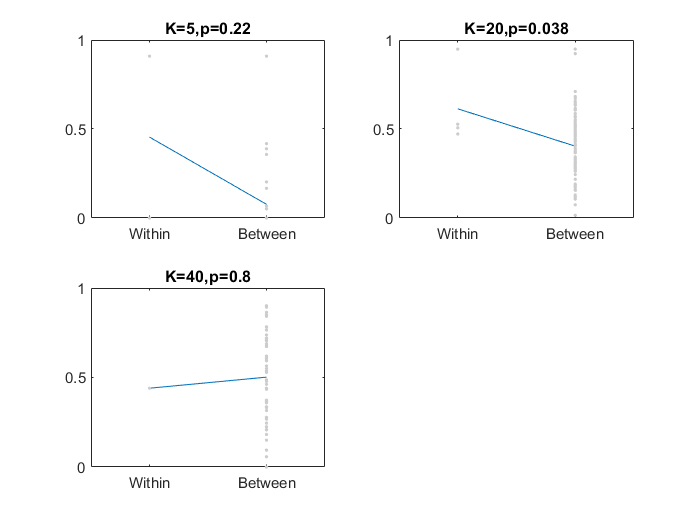

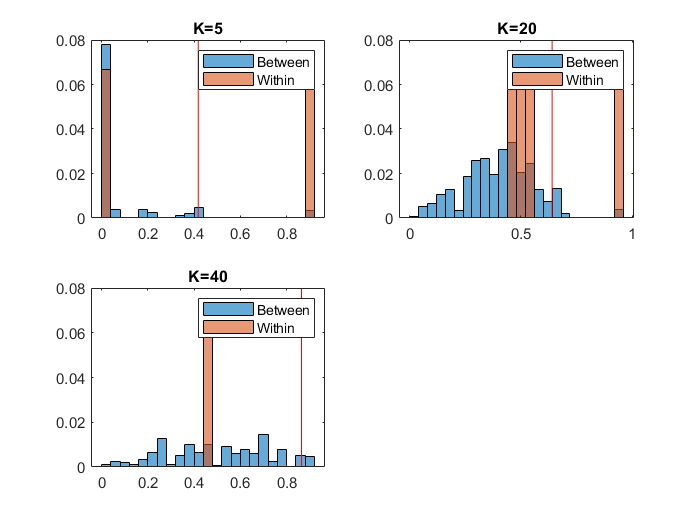

% event coverage for each animal
close all
covind=cell(N,nm);synwithin=[];synbetween=[];
for kind=1:3 % k index used 
for ind=1:N
    p=test(ind);
    for m=1:nm
        l=size(anti{1,1}.ca_cl{p,m},2);
        [totalcov]=evecoverage(l,anti{1,1}.allt{p,m}(kind),anti{1,1}.allk{p,m}(kind));
        % identify and remove trial onsets 
        onset = find(sum(reshape(E{p}{1}.BehaviorVectors(1:30*l,4),30,l),1));
        keep=ones(1,l);
        for i=1:length(onset)
            keep(onset(i):onset(i)+19)=0;
        end
        covind{ind,m}=totalcov;
        synwithin(kind,ind)=sum(all([covind{ind,1};covind{ind,2}],1))/min(sum(covind{ind,1}),sum(covind{ind,2}));
    end
end
% randomly match 100 pairs 
perm=cell(1,100);
for r = 1:100
    perm{r}=randperm(N*2);
    perm{r}=reshape(perm{r},N,2);
    while any(perm{r}(:,1)-perm{r}(:,2)==1) % make sure no same pair come together
        perm{r}=randperm(N*2);
        perm{r}=reshape(perm{r},N,2);
    end 
for ind=1:N
    [p1,m1]=ind2sub([N,2],perm{r}(ind,1));[p2,m2]=ind2sub([N,2],perm{r}(ind,2));
    l=min(length(covind{p1,m1}),length(covind{p2,m2}));
    synbetween(ind,r)=sum(all([covind{p1,m1}(1:l);covind{p2,m2}(1:l)],1))/min(sum(covind{p1,m1}(1:l)),sum(covind{p2,m2}(1:l)));
end
end
% report statistics using the rank sum test 
rs(kind)=ranksum(synwithin(kind,:),synbetween(:));
% plot
figure(1)
subplot(2,2,kind)
plot([nanmean(synwithin(kind,:)),nanmean(synbetween,'all')],'-');hold on
plot(ones(1,N),synwithin(kind,:),'.',"Color",0.8*[1,1,1]);
plot(repelem(2,1,N*100),synbetween(:),'.',"Color",0.8*[1,1,1]);
xlim([0.5 2.5]);xticks([1 2]);
xticklabels({'Within','Between'});
title(sprintf('K=%d,p=%.2g',klist{kind},rs(kind)))
figure(2) % histogram for distribution 
subplot(2,2,kind)
h1 = histogram(synbetween(:));
hold on
h2 = histogram(synwithin(kind,:));
h1.Normalization = 'probability';h1.BinWidth = 0.04;
h2.Normalization = 'probability';h2.BinWidth = 0.04;
q=quantile(synbetween(:),0.95);line([q q],ylim,'Color','r')
legend([h1 h2],{'Between','Within'})
title(sprintf('K=%d',klist{kind}))
end

rs

rs =     0.2185    0.0378    0.8025    0.3795


% synchronization with events of 3 Ks together (5s,20s,40s)

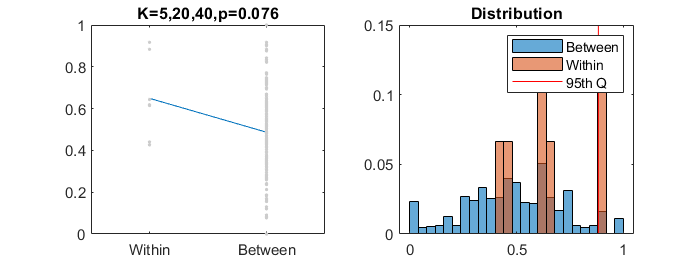

close all
covind=cell(N,nm);synwithin=[];synbetween=[];
kind=[1,2,3]; % k index used 
for ind=1:N
    p=test(ind);
    for m=1:nm
        % first round
        l=size(anti{1,1}.ca_cl{p,m},2);
        [totalcov]=evecoverage(l,anti{1,1}.allt{p,m}(kind),anti{1,1}.allk{p,m}(kind));
        % identify and remove trial onsets 
        onset = find(sum(reshape(E{p}{1}.BehaviorVectors(1:30*l,4),30,l),1));
        keep=ones(1,l);
        for i=1:length(onset)
            keep(onset(i):onset(i)+19)=0;
        end
        covind{ind,m}=totalcov;
        synwithin(ind)=sum(all([covind{ind,1};covind{ind,2}],1))/min(sum(covind{ind,1}),sum(covind{ind,2}));
    end
end
% randomly match 100 pairs 
perm=cell(1,100);
for r = 1:100
    perm{r}=randperm(N*2);
    perm{r}=reshape(perm{r},N,2);
    while any(perm{r}(:,1)-perm{r}(:,2)==1) % make sure no same pair come together
        perm{r}=randperm(N*2);
        perm{r}=reshape(perm{r},N,2);
    end 
for p=1:N
    [p1,m1]=ind2sub([N,2],perm{r}(p,1));[p2,m2]=ind2sub([N,2],perm{r}(p,2));
    l=min(length(covind{p1,m1}),length(covind{p2,m2}));
    synbetween(p,r)=sum(all([covind{p1,m1}(1:l);covind{p2,m2}(1:l)],1))/min(sum(covind{p1,m1}(1:l)),sum(covind{p2,m2}(1:l)));
end
end
% rank sum test
rsp=ranksum(synwithin,synbetween(:));
f=figure;f.Position(4)=0.5*f.Position(4);
subplot(1,2,1)
plot([nanmean(synwithin),nanmean(synbetween,'all')],'-');hold on
plot(ones(1,N),synwithin,'.',"Color",0.8*[1,1,1]);
plot(repelem(2,1,N*100),synbetween(:),'.',"Color",0.8*[1,1,1]);
xlim([0.5 2.5]);xticks([1 2]);
xticklabels({'Within','Between'});
title(sprintf('K=5,20,40,p=%.2g',rsp))
subplot(1,2,2)
h1 = histogram(synbetween(:));
hold on
h2 = histogram(synwithin);
h1.Normalization = 'probability';h1.BinWidth = 0.04;
h2.Normalization = 'probability';h2.BinWidth = 0.04;
q=quantile(synbetween(:),0.95);line([q q],ylim,'Color','r')
legend({'Between','Within','95th Q'});
title('Distribution')

Conclusion: border line significance; no change after remove trial onsets 